clc%simple MC
n=10000;
x=rand(1,n);
I1=sum(x.^0.5)/n

I1 = 0.6694

m=100;%importance sampling
n=10000;
for a=1:5
    b=1/((1/a)*(exp(-a)-1)+1);
    for i=1:m
        xx=rand(1,n);
        y=b*(1-exp(-a.*xx));
        yy=max(y)*rand(1,n);
        k=0;
        for j=1:n  
            if yy(j)<y(j) %%rejection
               k=k+1;
               f(k)= sqrt(xx(j))/y(j);              
            end
        end
        I(i)=sum(f)/k;
        f=zeros;
    end
    I2(a)=mean(I);
    var(a)=std(I)/sqrt(m);
    I=zeros;
end
I2

I2 =     0.6670    0.6667    0.6668    0.6667    0.6667


var

var =    1.0e-03 *

    0.2320    0.1484    0.0925    0.0865    0.1116


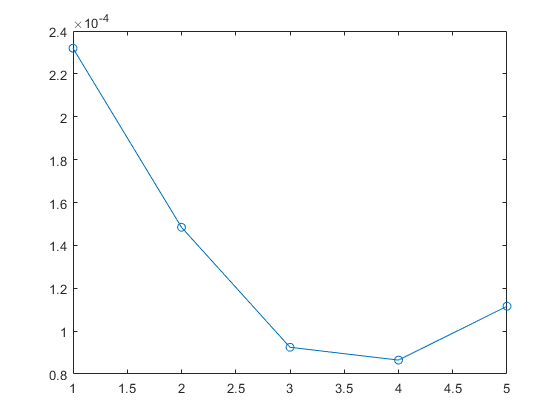

plot(var,'-o')

a=4 minimize variance